# Import saved neutron KERMA data 


%% Lung
filename = 'C:\Users\Lucas Sommer\LRZ Sync+Share\MATLAB\MATRAD\MCNP\KERMA_factors\neutronKERMA_2.txt';
delimiter = ' ';
formatSpec = '%f%f%[^\n\r]';
fileID = fopen(filename,'r');

dataArray = textscan(fileID, formatSpec, 'Delimiter', delimiter, 'MultipleDelimsAsOne', true, 'TextType', 'string',  'ReturnOnError', false);
fclose(fileID);

neutronKERMA_lung = [dataArray{1:end-1}];
clearvars filename delimiter formatSpec fileID dataArray ans;

%% Soft Tissue
filename = 'C:\Users\Lucas Sommer\LRZ Sync+Share\MATLAB\MATRAD\MCNP\KERMA_factors\neutronKERMA_3.txt';
delimiter = ' ';
formatSpec = '%f%f%[^\n\r]';
fileID = fopen(filename,'r');

dataArray = textscan(fileID, formatSpec, 'Delimiter', delimiter, 'MultipleDelimsAsOne', true, 'TextType', 'string',  'ReturnOnError', false);
fclose(fileID);

neutronKERMA_softTissue = [dataArray{1:end-1}];
clearvars filename delimiter formatSpec fileID dataArray ans;

%% Bone
filename = 'C:\Users\Lucas Sommer\LRZ Sync+Share\MATLAB\MATRAD\MCNP\KERMA_factors\neutronKERMA_4.txt';
delimiter = ' ';
formatSpec = '%f%f%[^\n\r]';
fileID = fopen(filename,'r');

dataArray = textscan(fileID, formatSpec, 'Delimiter', delimiter, 'MultipleDelimsAsOne', true, 'TextType', 'string',  'ReturnOnError', false);
fclose(fileID);

neutronKERMA_bone = [dataArray{1:end-1}];
clearvars filename delimiter formatSpec fileID dataArray ans;

%% Skin
filename = 'C:\Users\Lucas Sommer\LRZ Sync+Share\MATLAB\MATRAD\MCNP\KERMA_factors\neutronKERMA_5.txt';
delimiter = ' ';
formatSpec = '%f%f%[^\n\r]';
fileID = fopen(filename,'r');

dataArray = textscan(fileID, formatSpec, 'Delimiter', delimiter, 'MultipleDelimsAsOne', true, 'TextType', 'string',  'ReturnOnError', false);
fclose(fileID);

neutronKERMA_skin = [dataArray{1:end-1}];
clearvars filename delimiter formatSpec fileID dataArray ans;



# Plot neutron KERMA

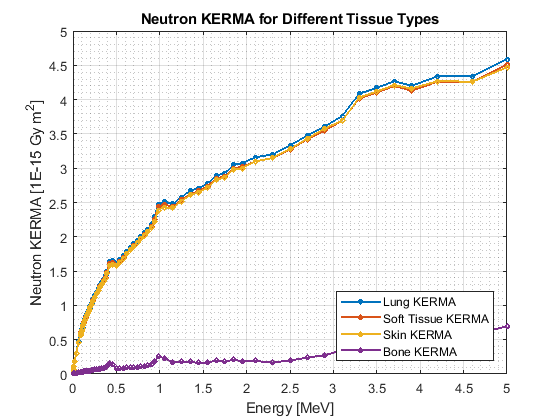

fig_neutronKERMA = figure;
plot(neutronKERMA_lung(:,1), neutronKERMA_lung(:,2)*1e15, '-o', 'LineWidth', 1.5, 'MarkerSize',3)
hold on
plot(neutronKERMA_lung(:,1), neutronKERMA_softTissue(:,2)*1e15, '-o', 'LineWidth', 1.5, 'MarkerSize',3)
plot(neutronKERMA_lung(:,1),neutronKERMA_skin(:,2)*1e15, '-o', 'LineWidth', 1.5, 'MarkerSize',3)
plot(neutronKERMA_lung(:,1),neutronKERMA_bone(:,2)*1e15, '-o', 'LineWidth', 1.5, 'MarkerSize',3)
legend({'Lung KERMA', 'Soft Tissue KERMA', 'Skin KERMA', 'Bone KERMA'}, 'Location', 'southeast');
title(['Neutron KERMA for Different Tissue Types']);
ylabel('Neutron KERMA [1E-15 Gy m^2]');
xlabel('Energy [MeV]');
xlim([0 5])

grid on 
grid minor

# Import saved photon KERMA data 


%% Lung
filename = 'C:\Users\Lucas Sommer\LRZ Sync+Share\MATLAB\MATRAD\MCNP\KERMA_factors\photonKERMA_2.txt';
delimiter = ' ';
formatSpec = '%f%f%[^\n\r]';
fileID = fopen(filename,'r');

dataArray = textscan(fileID, formatSpec, 'Delimiter', delimiter, 'MultipleDelimsAsOne', true, 'TextType', 'string',  'ReturnOnError', false);
fclose(fileID);

photonKERMA_lung = [dataArray{1:end-1}];
clearvars filename delimiter formatSpec fileID dataArray ans;

%% Soft Tissue
filename = 'C:\Users\Lucas Sommer\LRZ Sync+Share\MATLAB\MATRAD\MCNP\KERMA_factors\photonKERMA_3.txt';
delimiter = ' ';
formatSpec = '%f%f%[^\n\r]';
fileID = fopen(filename,'r');

dataArray = textscan(fileID, formatSpec, 'Delimiter', delimiter, 'MultipleDelimsAsOne', true, 'TextType', 'string',  'ReturnOnError', false);
fclose(fileID);

photonKERMA_softTissue = [dataArray{1:end-1}];
clearvars filename delimiter formatSpec fileID dataArray ans;

%% Bone
filename = 'C:\Users\Lucas Sommer\LRZ Sync+Share\MATLAB\MATRAD\MCNP\KERMA_factors\photonKERMA_4.txt';
delimiter = ' ';
formatSpec = '%f%f%[^\n\r]';
fileID = fopen(filename,'r');

dataArray = textscan(fileID, formatSpec, 'Delimiter', delimiter, 'MultipleDelimsAsOne', true, 'TextType', 'string',  'ReturnOnError', false);
fclose(fileID);

photonKERMA_bone = [dataArray{1:end-1}];
clearvars filename delimiter formatSpec fileID dataArray ans;

%% Skin
filename = 'C:\Users\Lucas Sommer\LRZ Sync+Share\MATLAB\MATRAD\MCNP\KERMA_factors\photonKERMA_5.txt';
delimiter = ' ';
formatSpec = '%f%f%[^\n\r]';
fileID = fopen(filename,'r');

dataArray = textscan(fileID, formatSpec, 'Delimiter', delimiter, 'MultipleDelimsAsOne', true, 'TextType', 'string',  'ReturnOnError', false);
fclose(fileID);

photonKERMA_skin = [dataArray{1:end-1}];
clearvars filename delimiter formatSpec fileID dataArray ans;



# Plot photon KERMA

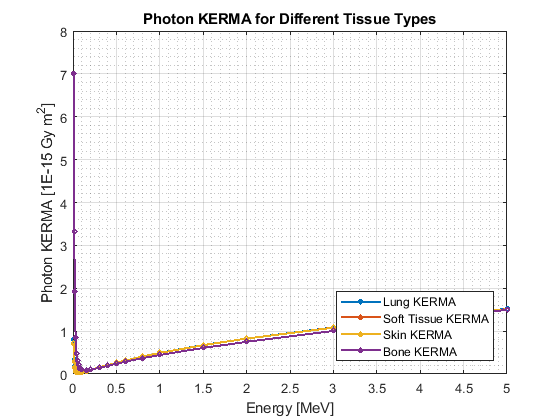

fig_neutronKERMA = figure;
plot(photonKERMA_lung(:,1), photonKERMA_lung(:,2)*1e15, '-o', 'LineWidth', 1.5, 'MarkerSize',3)
hold on
plot(photonKERMA_lung(:,1), photonKERMA_softTissue(:,2)*1e15, '-o', 'LineWidth', 1.5, 'MarkerSize',3)
plot(photonKERMA_lung(:,1),photonKERMA_skin(:,2)*1e15, '-o', 'LineWidth', 1.5, 'MarkerSize',3)
plot(photonKERMA_lung(:,1),photonKERMA_bone(:,2)*1e15, '-o', 'LineWidth', 1.5, 'MarkerSize',3)
legend({'Lung KERMA', 'Soft Tissue KERMA', 'Skin KERMA', 'Bone KERMA'}, 'Location', 'southeast');
title(['Photon KERMA for Different Tissue Types']);
ylabel('Photon KERMA [1E-15 Gy m^2]');
xlabel('Energy [MeV]');
xlim([0 5])
grid on 
grid minor